# REM Paper - Figures

By: Trent Furlong

## About

This code allows the user to generate the described figures used in the REM paper.

Note: The referenced figures have subplots corresponding to different mode shapes and/or boundary conditions. This code only generates the results corresponding to a given figure's subplot.

## REM Parameters

clear
% --- Predicted Models ---
params.M = 50;                     % Number of elements
params.dt = 0.0005;                % Time resolution, [s]
params.fs = 1/params.dt;           % Sampling frequency, [Hz]
% Other properties
params.T = 0.5;                    % Duration, [s]
% params.dx = 0.0005;                % Element spatial resolution, [m]
params.dx = 1/params.M; 
params.nmax = 3;                   % Maximum number of modes
params.normalize=true;             % Normalize the displacement, [logical]
% params.SLocs = 1 - 1/params.M;

### Figure: Clamped-Free Beam

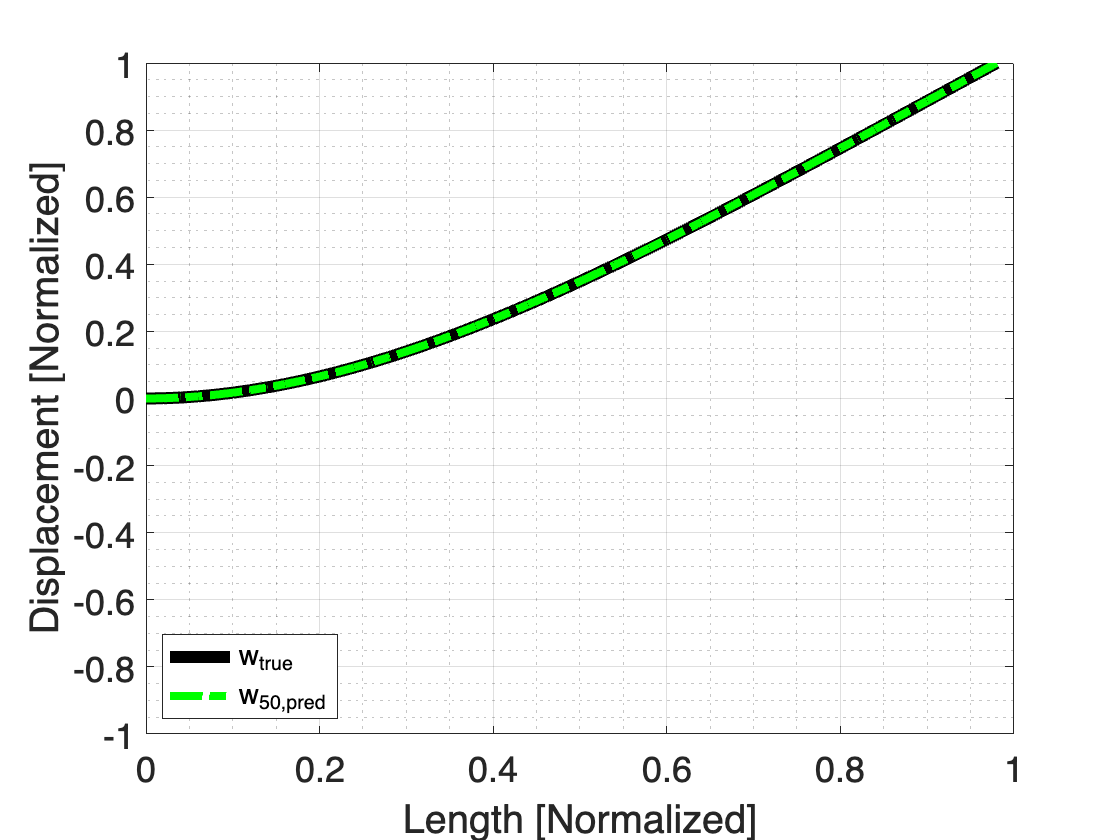

% Define Boundary Conditions
params.BCcase = "Clamped-Free";

% Define cases
Mcases = [2,10,50];      % M-elements
Nmodes = 1:params.nmax;  % n-th Mode

% Choose the casese
params.M = Mcases(3);
params.dx = 1/(params.M);
% x = linspace(0,1,params.M);
params.SLocs = 1 - 1/params.M;
nn = Nmodes(1);

% Define any material properties
params.EI = 1e3*ones(1,params.M);  % Flexural rigidity, [Pa m^4]
params.mu = 1*ones(1,params.M);    % Linear mass density, [kg/m];

% Get true mode shapes
[x, phi, omega] = CantileverBeamModes(params.nmax, dx=params.dx);
% Animate the modes by frequency
[t,yxt_true] = AnimateModes(x, phi, omega, dt=params.dt, T=params.T, plotTF=false);

% Get REM predicted mode shapes
[~, yxt_pred, ~, ~] = get_Modes_REM(params);

% Get metrics
[maxDiff, Rsq] = compare_Results(yxt_true, yxt_pred, nn);

% Plot maximum response
plot_MaxResponse(x, yxt_true, yxt_pred, params, nn)

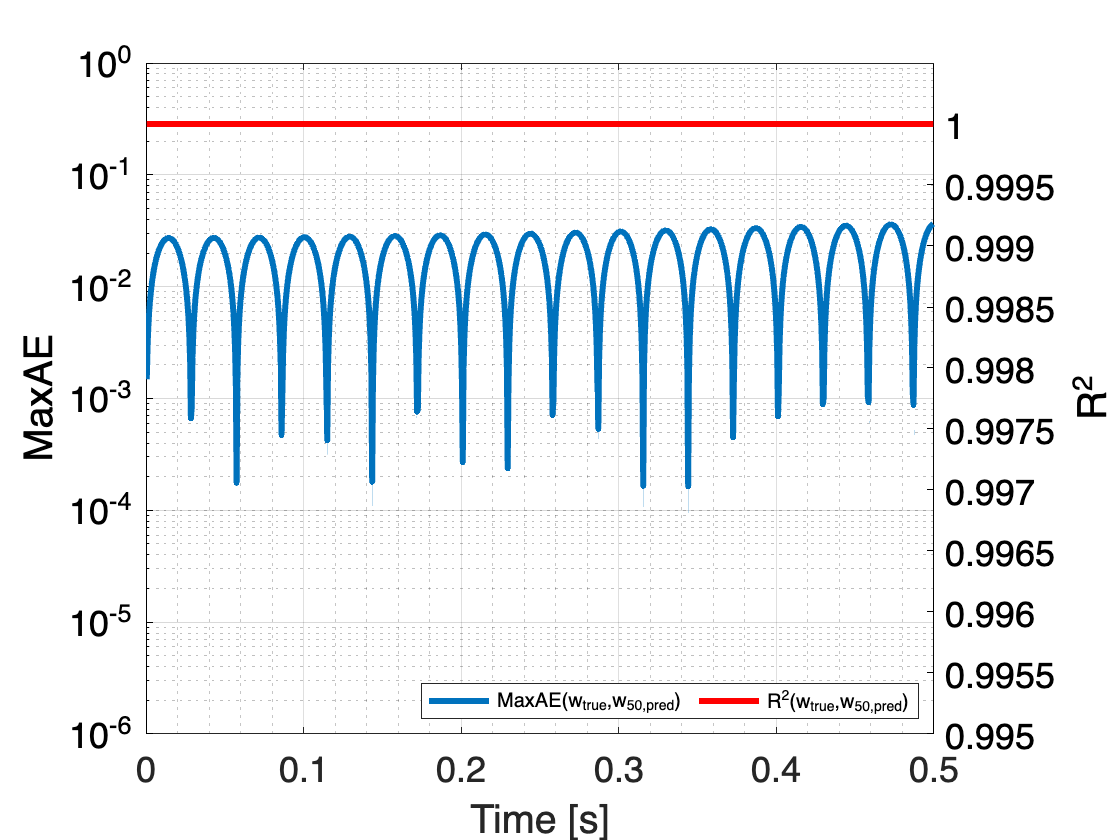

% Plot metrics
plot_Metrics(t, maxDiff, Rsq, params, nn)

### Figure: Free-Free Beam

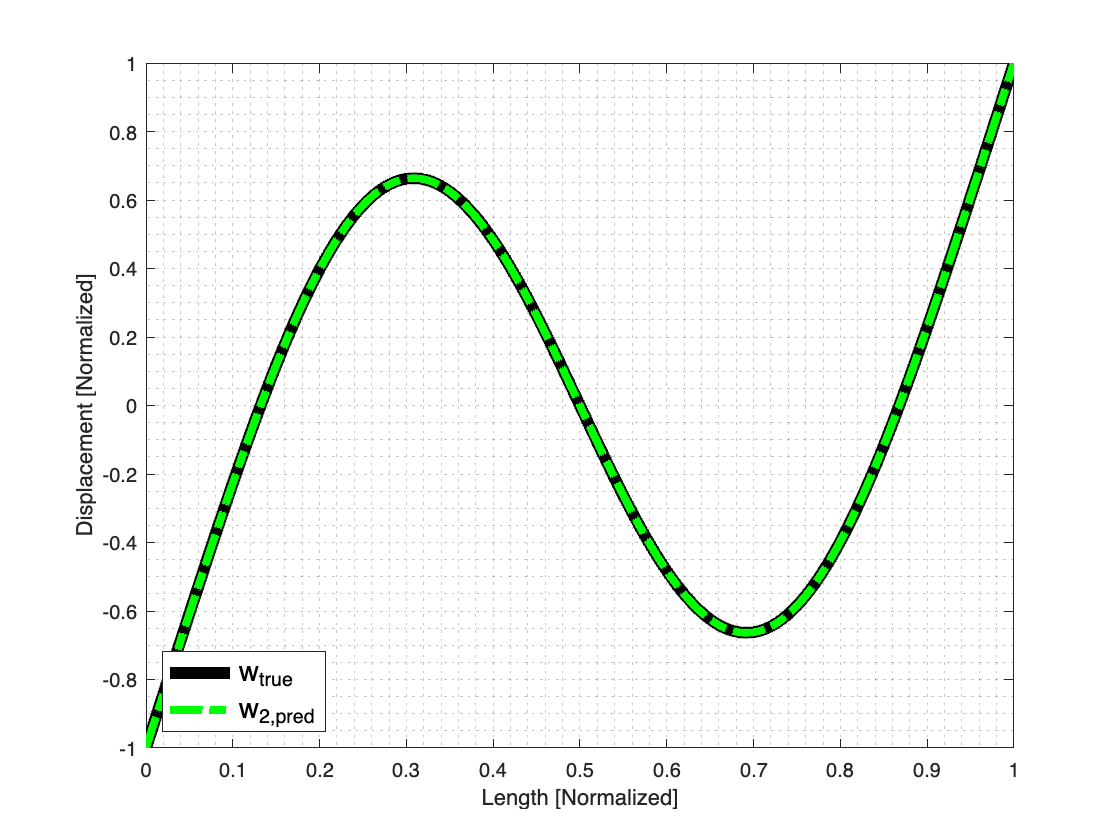

% Define Boundary Conditions
params.BCcase = "Free-Free";

% Define cases
Mcases = [2,10,50];      % M-elements
Nmodes = 1:params.nmax;  % n-th Mode

% Choose the casese
params.M = Mcases(1);
nn = Nmodes(2);

% Define any material properties
params.EI = 1e3*ones(1,params.M);  % Flexural rigidity, [Pa m^4]
params.mu = 1*ones(1,params.M);    % Linear mass density, [kg/m];

% Get true mode shapes
[x, phi, omega] = FreeFreeBeamModes(params.nmax, Y=params.EI, rho=params.mu, dx=params.dx);
% Animate the modes by frequency
[t,yxt_true] = AnimateModes(x, phi, omega, dt=params.dt, T=params.T, plotTF=false);

% Get REM predicted mode shapes
[~, yxt_pred, ~, ~] = get_Modes_REM(params);

% Get metrics
[maxDiff, Rsq] = compare_Results(yxt_true, yxt_pred, nn);

% Plot maximum response
plot_MaxResponse(x, yxt_true, yxt_pred, params, nn)

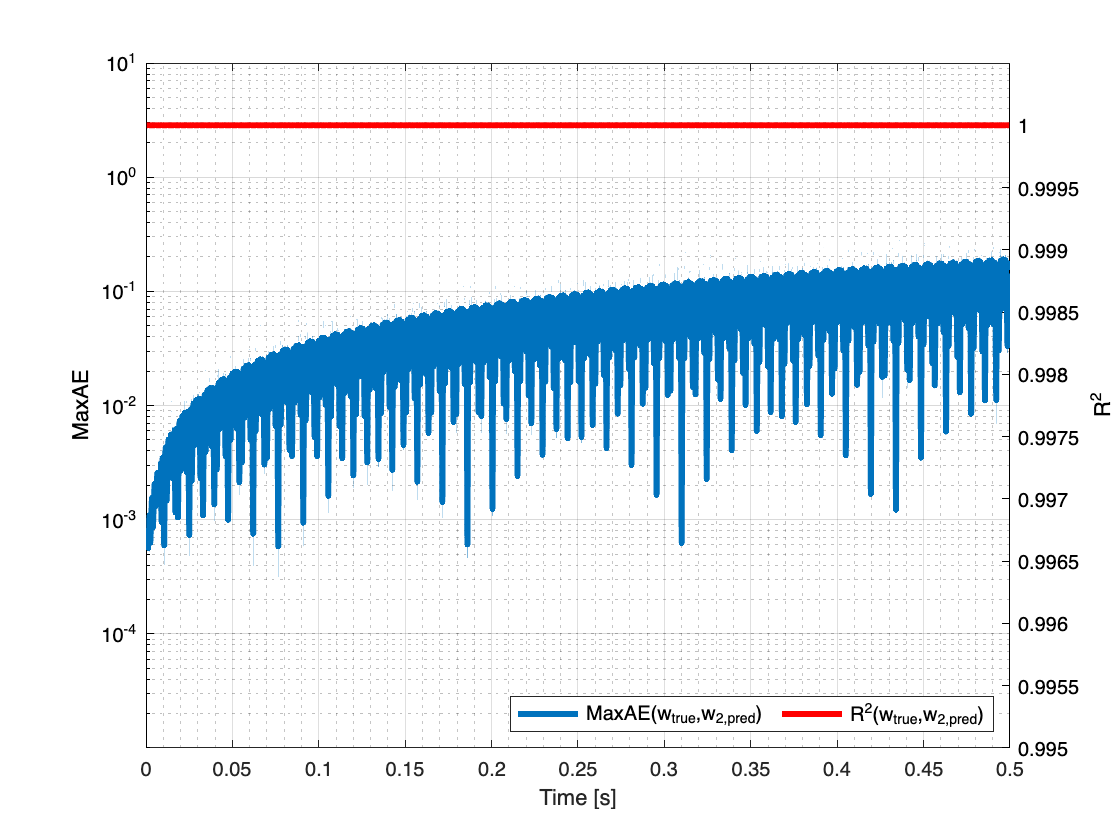

% Plot metrics
plot_Metrics(t, maxDiff, Rsq, params, nn)

### Figure: Pinned-Pinned Beam

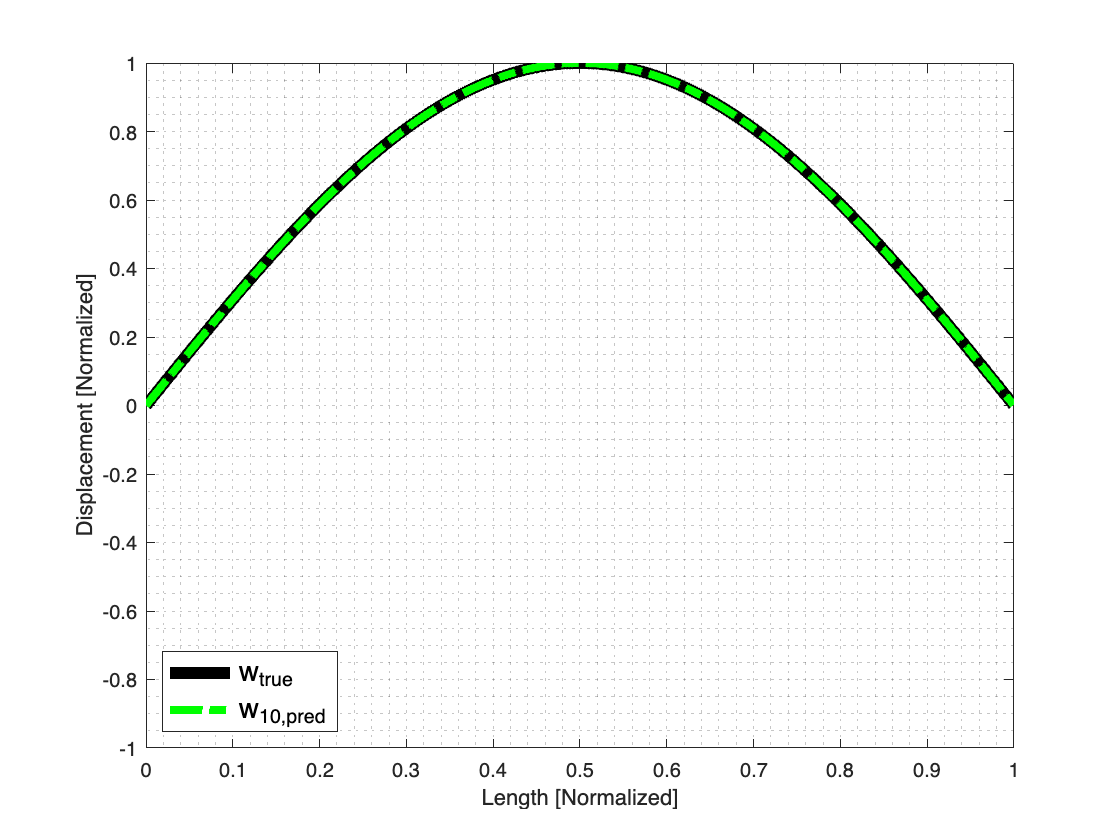

% Define Boundary Conditions
params.BCcase = "Pinned-Pinned";

% Define cases
Mcases = [2,10,50];      % M-elements
Nmodes = 1:params.nmax;  % n-th Mode

% Choose the casese
params.M = Mcases(2);
nn = Nmodes(1);

% Define any material properties
params.EI = 1e3*ones(1,params.M);  % Flexural rigidity, [Pa m^4]
params.mu = 1*ones(1,params.M);    % Linear mass density, [kg/m];

% Get true mode shapes
[x, phi, omega] = PinPinBeamModes(params.nmax, Y=params.EI, rho=params.mu, dx=params.dx);
% Animate the modes by frequency
[t,yxt_true] = AnimateModes(x, phi, omega, dt=params.dt, T=params.T, plotTF=false);

% Get REM predicted mode shapes
[~, yxt_pred, ~, ~] = get_Modes_REM(params);

% Get metrics
[maxDiff, Rsq] = compare_Results(yxt_true, yxt_pred, nn);

% Plot maximum response
plot_MaxResponse(x, yxt_true, yxt_pred, params, nn)

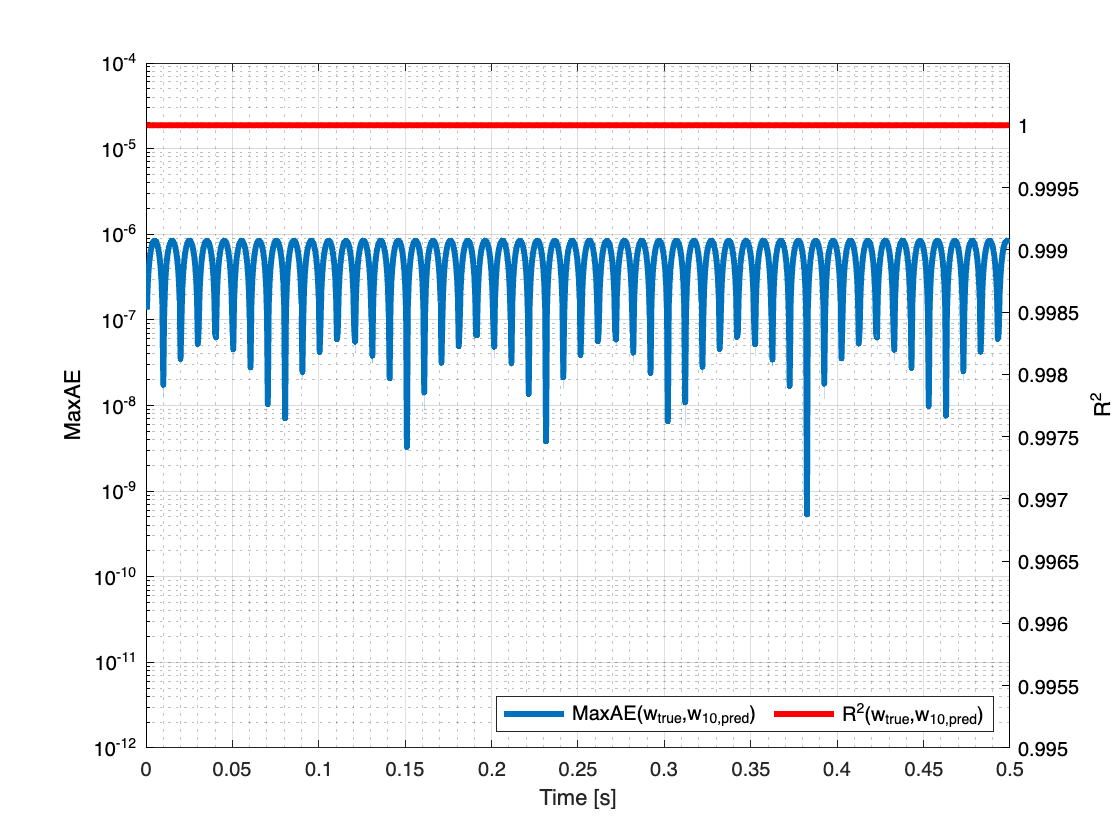

% Plot metrics
plot_Metrics(t, maxDiff, Rsq, params, nn)

## Simulating Beam Damage

clear
% --- Predicted Models ---
params.M = 50;                     % Number of elements
params.dt = 0.0005;                % Time resolution, [s]
params.fs = 1/params.dt;           % Sampling frequency, [Hz]
% Other properties
params.T = 0.5;                    % Duration, [s]
params.dx = 0.0005;                % Element spatial resolution, [m]
params.nmax = 3;                   % Maximum number of modes
% Define Boundary Conditions
params.BCcase = "Free-Free";

% Define current mode shape
nn = 1;

% Define any material properties
EI0 = 1e3;
params.EI = EI0*ones(1,params.M);  % Flexural rigidity, [Pa m^4]
params.mu = 1*ones(1,params.M);    % Linear mass density, [kg/m];

% Define element(s) where fault occurs
fault_Loc = [25,26];
% Define change in EI and root EI-values
delta_EI = [1.0, 0.99, 0.95, 0.9, 0.75, 0.5];

### Figure: Displacement

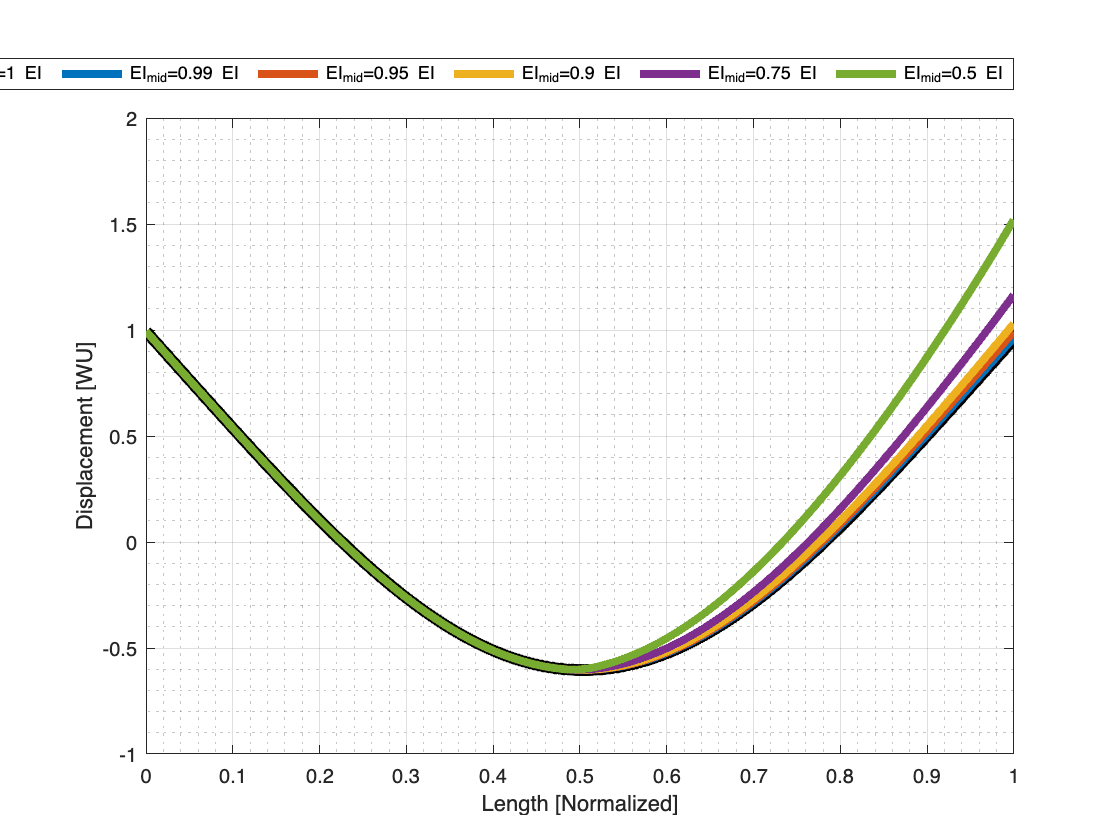

% Normalize the displacement, [logical]
params.normalize = false;
% Plot results
plot_SimulatedDamage(EI0, delta_EI, fault_Loc, params, nn)

### Figure: Displacement (Normalized)

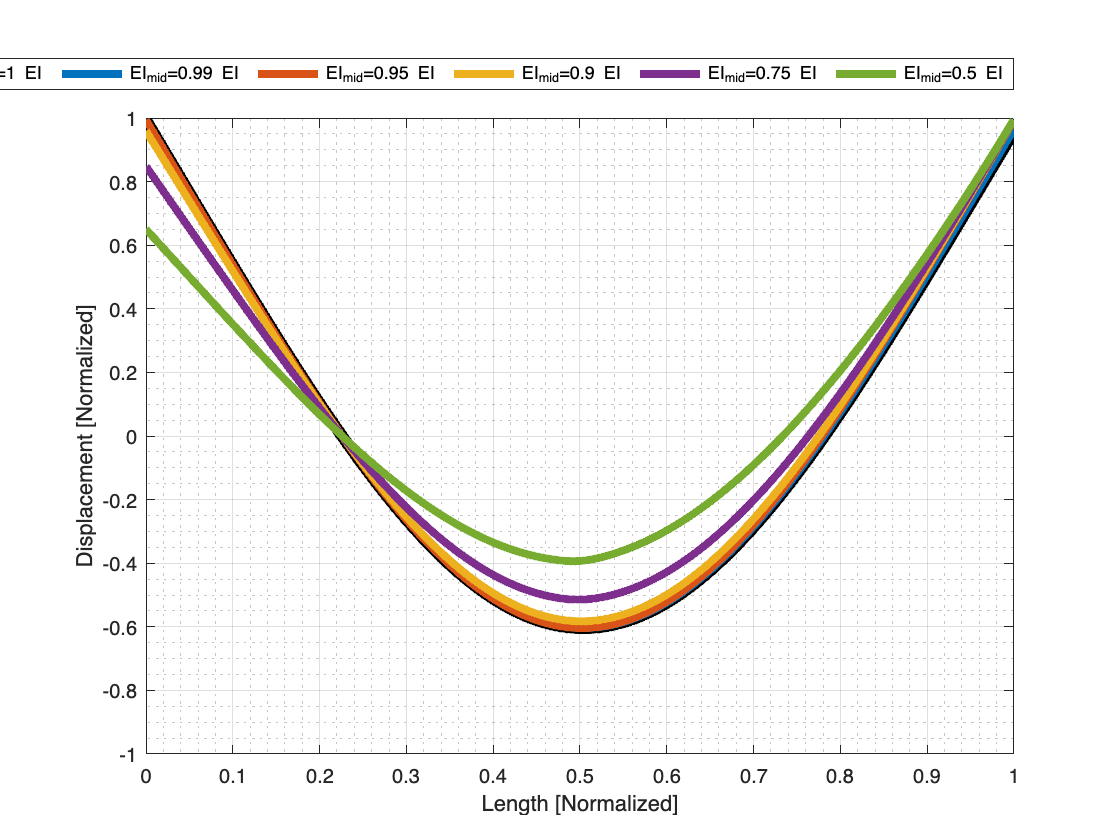

% Normalize the displacement, [logical]
params.normalize = true;
% Plot results
plot_SimulatedDamage(EI0, delta_EI, fault_Loc, params, nn)

### Figure: REM & COMSOL Comparisons

See "REM_COMSOL_Comparison.mlx"

### REM & FEM Comparisons

For a more accurate comparison between REM and FEM, each element of the REM will have a spatial sampling equal to 1/M

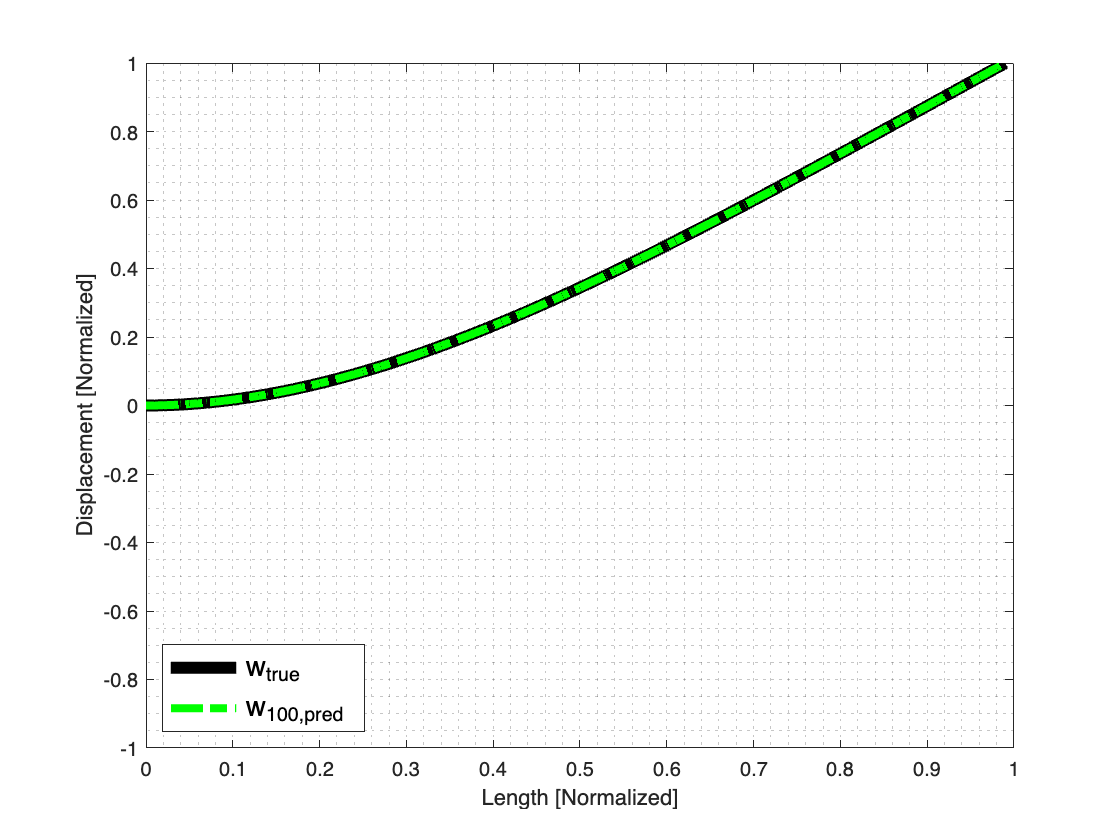

clear
% --- Predicted Models ---
params.M = 100;                     % Number of elements
params.dt = 0.0005;                % Time resolution, [s]
params.fs = 1/params.dt;           % Sampling frequency, [Hz]
% Other properties
params.T = 0.5;                    % Duration, [s]
% params.dx = 0.0005;                % Element spatial resolution, [m]
params.dx = 1/params.M; 
params.nmax = 3;                   % Maximum number of modes
params.normalize=true;             % Normalize the displacement, [logical]
% params.SLocs = 1 - 1/params.M;

% Define Boundary Conditions
params.BCcase = "Clamped-Free";

% Define cases
Mcases = [2,10,50];      % M-elements
Nmodes = 1:params.nmax;  % n-th Mode

% Choose the casese
% params.M = Mcases(3);
params.dx = 1/(params.M);
% x = linspace(0,1,params.M);
params.SLocs = 1 - 1/params.M;
nn = Nmodes(1);

% Define any material properties
params.EI = 1e3*ones(1,params.M);  % Flexural rigidity, [Pa m^4]
params.mu = 1*ones(1,params.M);    % Linear mass density, [kg/m];

% Get true mode shapes
[x, phi, omega] = CantileverBeamModes(params.nmax, dx=params.dx);
% Animate the modes by frequency
[t,yxt_true] = AnimateModes(x, phi, omega, dt=params.dt, T=params.T, plotTF=false);

% Get REM predicted mode shapes
[~, yxt_pred, ~, ~] = get_Modes_REM(params);

% Get metrics
[maxDiff, Rsq] = compare_Results(yxt_true, yxt_pred, nn);

% Plot maximum response
plot_MaxResponse(x, yxt_true, yxt_pred, params, nn)

Time the REM calculation

clear
% --- Predicted Models ---
params.dt = 0.0005;                % Time resolution, [s]
params.fs = 1/params.dt;           % Sampling frequency, [Hz]
% Other properties
params.T = 0.5;                    % Duration, [s]
params.nmax = 3;                   % Maximum number of modes
params.normalize=true;             % Normalize the displacement, [logical]

% Define Boundary Conditions
params.BCcase = "Clamped-Free";

% Define cases
Mcases = [10,50,100,500,1000,5000,10000,50000];      % M-elements
tclock = zeros(size(Mcases));
for ii = 1:length(Mcases)
    params.M = Mcases(ii);
    params.dx = 1/(params.M);
    params.SLocs = 1 - 1/params.M;
    % Define any material properties
    params.EI = 1e3*ones(1,params.M);  % Flexural rigidity, [Pa m^4]
    params.mu = 1*ones(1,params.M);    % Linear mass density, [kg/m];
    
    % Get REM predicted mode shapes
    sprintf("M = %d", Mcases(ii))
    tic
    [x, yxt_pred, phi_n, omega_n] = get_Modes_REM(params);
    tclock(ii) = toc;
    sprintf("Duration = %.4f [s]", tclock(ii))
end

ans = "M = 10"

ans = "Duration = 0.1517 [s]"

ans = "M = 50"

ans = "Duration = 0.4561 [s]"

ans = "M = 100"

ans = "Duration = 0.8585 [s]"

ans = "M = 500"

ans = "Duration = 4.1263 [s]"

ans = "M = 1000"

ans = "Duration = 8.2318 [s]"

ans = "M = 5000"

ans = "Duration = 41.3144 [s]"

ans = "M = 10000"

ans = "Duration = 82.4411 [s]"

ans = "M = 50000"

ans = "Duration = 400.3726 [s]"

Mcases

Mcases =           10          50         100         500        1000        5000       10000       50000


tclock

tclock =     0.1517    0.4561    0.8585    4.1263    8.2318   41.3144   82.4411  400.3726


tclock/60

ans =     0.0025    0.0076    0.0143    0.0688    0.1372    0.6886    1.3740    6.6729


#### Curve Fitting Analysis

The best fit is a 'poly2' fit, but the REM data appears to be primarily linear (i.e., 'poly1'), where increasing the number of elements linearly increases the computation time.

[fit_poly1, gof1] = fit(Mcases.', tclock.', 'poly1')

fit_poly1 =      Linear model Poly1:
     fit_poly1(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    0.008005  (0.007956, 0.008055)
       p2 =      0.5398  (-0.3601, 1.44)

gof1 = struct with fields:
           sse: 5.1196
       rsquare: 1.0000
           dfe: 6
    adjrsquare: 1.0000
          rmse: 0.9237


[fit_poly2, gof2] = fit(Mcases.', tclock.', 'poly2')

fit_poly2 =      Linear model Poly2:
     fit_poly2(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =  -5.815e-09  (-6.157e-09, -5.473e-09)
       p2 =    0.008298  (0.008281, 0.008316)
       p3 =    0.009692  (-0.05176, 0.07114)

gof2 = struct with fields:
           sse: 0.0134
       rsquare: 1.0000
           dfe: 5
    adjrsquare: 1.0000
          rmse: 0.0517


[fit_pow1, gof3] = fit(Mcases.', tclock.', 'power1')

fit_pow1 =      General model Power1:
     fit_pow1(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =    0.009524  (0.009212, 0.009837)
       b =       0.984  (0.9809, 0.987)

gof3 = struct with fields:
           sse: 0.2512
       rsquare: 1.0000
           dfe: 6
    adjrsquare: 1.0000
          rmse: 0.2046


[fit_exp1, gof4] = fit(Mcases.', tclock.', 'exp1')

fit_exp1 =      General model Exp1:
     fit_exp1(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       19.51  (-1.594, 40.61)
       b =   6.048e-05  (3.858e-05, 8.237e-05)

gof4 = struct with fields:
           sse: 3.9107e+03
       rsquare: 0.9705
           dfe: 6
    adjrsquare: 0.9656
          rmse: 25.5300


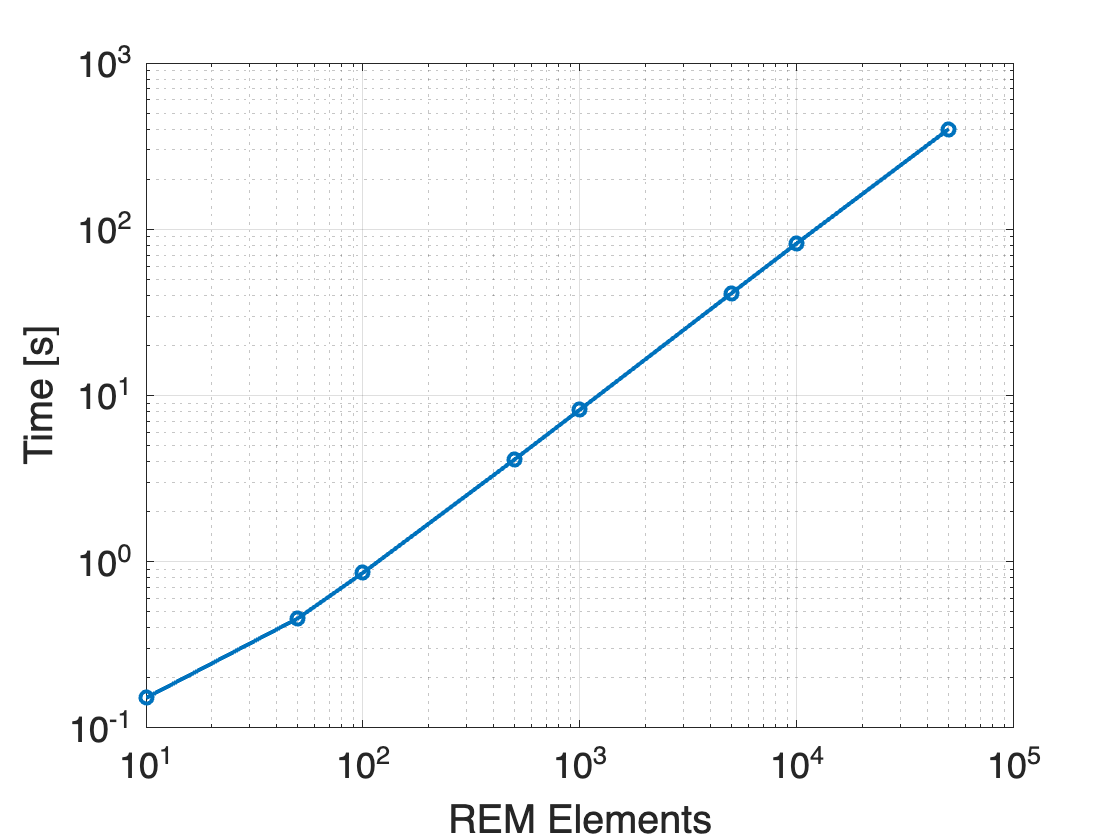

figure;
loglog(Mcases, tclock,'-o')
xlabel('REM Elements')
ylabel('Time [s]')

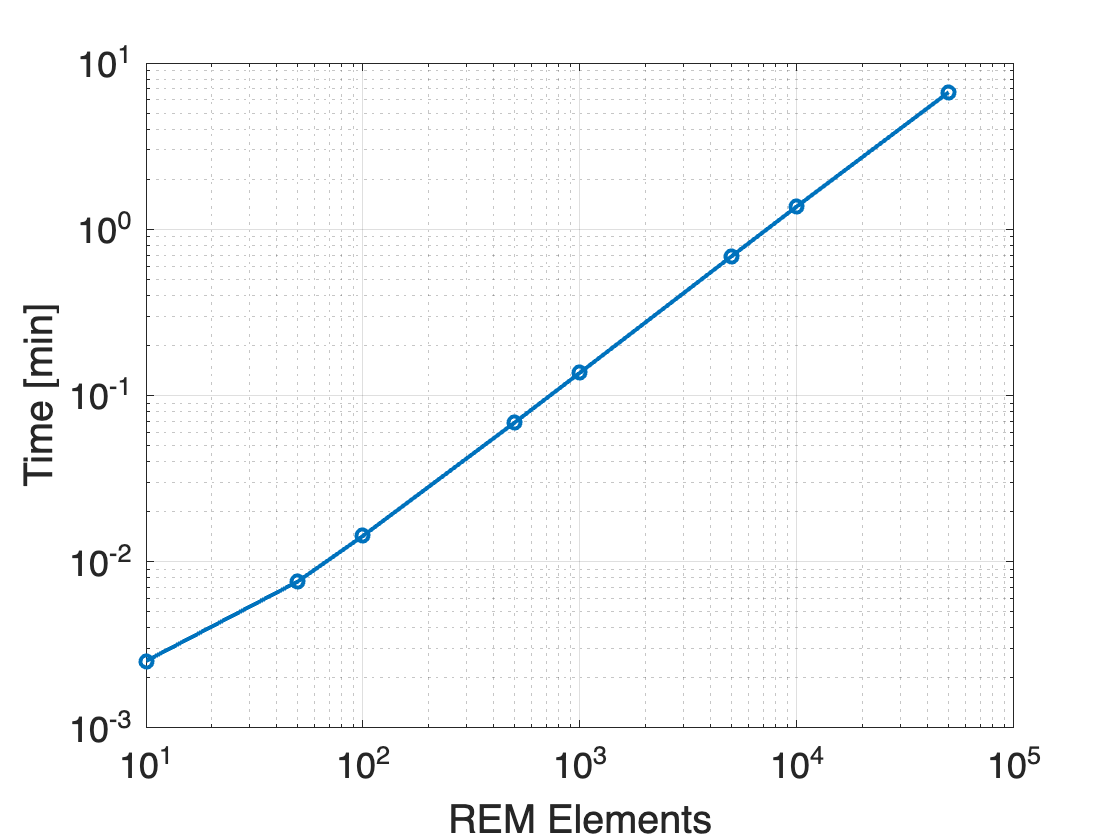

figure;
loglog(Mcases, tclock/60, '-o')
xlabel('REM Elements')
ylabel('Time [min]')

## Embedded Functions

function [x, yxt, phi_n, omega_n] = get_Modes_REM(params)
    % Parse parameters
    M = params.M;
    dt = params.dt;
    fs = params.fs;
    T = params.T;
    dx = params.dx;
    EI = params.EI;
    mu = params.mu;
    BCcase = params.BCcase;
    nmax = params.nmax;
    normalize = params.normalize;
    SLocs = params.SLocs;
    t = 0:dt:T-dt;
    
    % Instantiate loop variables
    x = (0:dx:1-dx).';
    % x = linspace(0,1,M);
    phi_n = zeros(length(x), nmax);  % Mode shapes (normalized)
    omega_n = zeros(M, nmax);        % Resonant angular freq., [rad/s]
    yxt = zeros(numel(x), numel(t), nmax);
    for n = 1:nmax
        % Get time series response from t=0:T-dt
        [~,~,yxt_n,~,phi_elem,omega_elem] = FlexuralBending_REM(M,fs,...
                                            T=T,...
                                            dx=dx,...
                                            n=n,...
                                            EI=EI,...
                                            mu=mu,...
                                            BCcase=BCcase, ...
                                            normalize=normalize, ...
                                            SLocs=SLocs);
        phi_n(:,n) = phi_elem(:);
        omega_n(:,n) = omega_elem.';
        yxt(:,:,n) = reshape(yxt_n, (size(yxt_n,1) * size(yxt_n,2)), size(yxt_n,3));
    end
    
end

function [x_elem,phi,omega] = CantileverBeamModes(N,options)
    arguments
        N                   % Number of mode shapes
        options.An = 1/2    % Mode shape coefficient(s)
        options.Y = 1e6     % Young's modulus, [Pa]
        options.rho = 1000  % Density
        options.kappa = 1   % Radius of gyration, [m]
        options.L = 1       % Length
        options.M = 1       % Number of subelements
        options.dx = 0.005  % Spatial resolution
    end
    % Parse 'options' variables
    An = options.An;
    Y = options.Y;
    rho = options.rho;
    kappa = options.kappa;
    L = options.L;
    M = options.M;
    dx = options.dx;

    % Define length of the beam
    x = (0:dx:L-dx)';               % Spatial grid along x-axis, [m]

    % Partition beam into M number of subelements
    x_elem = reshape(x,[],M);       % Define sub element x-axes
    
    % Define wavespeed
    cL = sqrt(Y/rho);               % Longitudinal wavespeed, [m/s]

    % --- Define Natural frequencies ---
    % Define the number of natural frequencies to calculate
    n = (1:N).';                    % nth natural frequency
    % Define the natural frequencies
    fn = ((2*n - 1).^2) * ((pi * kappa * cL)./(8 * L^2));
    fn(1,:) = ((1.194).^2) * ((pi * kappa * cL)/(8 * L^2));
    if N > 1
        fn(2,:) = ((2.988).^2) * ((pi * kappa * cL)/(8 * L^2));
    end
    % Define omega and v
    omega = 2*pi*fn;                % Angular frequency, [rad/s]
    v = sqrt(omega * kappa .* cL);  % Flexural wavespeed, [m/s]

    % --- Define the mode shapes ---
    % Define functional input parameters
    X = zeros([size(x_elem,1),size(x_elem,2),N]);
    XL = zeros([size(x_elem,1),size(x_elem,2),N]);
    for ii = 1:N
        X(:,:,ii) = x_elem .* (omega(ii,:)./v(ii,:));
        XL(:,:,ii) = L*ones(size(x_elem)) .* (omega(ii,:)./v(ii,:));
    end
    
    % Define the coefficients A and B
    Bn = -An * (( cosh(XL) + cos(XL) ) ./ ( sinh(XL) + sin(XL) ));
    
    % Define the mode shapes
    phi = An * ( cosh(X) - cos(X) ) + Bn.*( sinh(X) - sin(X) );
    if M == 1
        phi = squeeze(phi);
    end
end

function [x_elem,phi,omega] = FreeFreeBeamModes(N,options)
    arguments
        N                   % Number of mode shapes
        options.An = 1/2    % Mode shape coefficient(s)
        options.Y = 1e6     % Young's modulus, [Pa]
        options.rho = 1000  % Density
        options.kappa = 1   % Radius of gyration, [m]
        options.L = 1       % Length
        options.M = 1       % Number of subelements
        options.dx = 0.005  % Spatial resolution
    end
    % Parse 'options' variables
    An = options.An;
    Y = options.Y;
    rho = options.rho;
    kappa = options.kappa;
    L = options.L;
    M = options.M;
    dx = options.dx;

    % Define length of the beam
    x = (0:dx:L-dx)';               % Spatial grid along x-axis, [m]

    % Partition beam into M number of subelements
    x_elem = reshape(x,[],M);       % Define sub element x-axes
    
    % Define wavespeed
    cL = sqrt(Y/rho);               % Longitudinal wavespeed, [m/s]

    % --- Define Natural frequencies ---
    % Define the number of natural frequencies to calculate
    n = (1:N).';                    % nth natural frequency
    % Define the natural frequencies
    fn = ((2*n + 1).^2) * ((pi * kappa * cL)./(8 * L^2));
    fn(1,:) = ((3.011).^2) * ((pi * kappa * cL)/(8 * L^2));
    % Define omega and v
    omega = 2*pi*fn;                % Angular frequency, [rad/s]
    v = sqrt(omega * kappa .* cL);  % Flexural wavespeed, [m/s]

    % --- Define the mode shapes ---
    % Define functional input parameters
    X = zeros([size(x_elem,1),size(x_elem,2),N]);
    XL = zeros([size(x_elem,1),size(x_elem,2),N]);
    for ii = 1:N
        X(:,:,ii) = x_elem .* (omega(ii,:)./v(ii,:));
        XL(:,:,ii) = L*ones(size(x_elem)) .* (omega(ii,:)./v(ii,:));
    end
    
    % Define the coefficients A and B
    Bn = -An * (( cosh(XL) - cos(XL) ) ./ ( sinh(XL) - sin(XL) ));
    
    % Define the mode shapes
    phi = An * ( cosh(X) + cos(X) ) + Bn.*( sinh(X) + sin(X) );
    if M == 1
        phi = squeeze(phi);
    end
end

function [x_elem,phi,omega] = PinPinBeamModes(N,options)
    arguments
        N                   % Number of mode shapes
        options.An = 1    % Mode shape coefficient(s)
        options.Y = 1e6     % Young's modulus, [Pa]
        options.rho = 1000  % Density
        options.kappa = 1   % Radius of gyration, [m]
        options.L = 1       % Length
        options.M = 1       % Number of subelements
        options.dx = 0.005  % Spatial resolution
    end
    % Parse 'options' variables
    An = options.An;
    Y = options.Y;
    rho = options.rho;
    kappa = options.kappa;
    L = options.L;
    M = options.M;
    dx = options.dx;

    % Define length of the beam
    x = (0:dx:L-dx)';               % Spatial grid along x-axis, [m]

    % Partition beam into M number of subelements
    x_elem = reshape(x,[],M);       % Define sub element x-axes
    
    % Define wavespeed
    cL = sqrt(Y/rho);               % Longitudinal wavespeed, [m/s]

    % --- Define Natural frequencies ---
    % Define the number of natural frequencies to calculate
    n = (1:N).';                        % nth natural frequency
    % Define omega and v
    omega = kappa .* cL .* (n*pi/L).^2; % Angular frequency, [rad/s]
    v = sqrt(omega * kappa .* cL);      % Flexural wavespeed, [m/s]

    % --- Define the mode shapes ---
    % Define functional input parameters
    X = zeros([size(x_elem,1),size(x_elem,2),N]);
    for ii = 1:N
        X(:,:,ii) = x_elem .* (omega(ii,:)./v(ii,:));
    end
    
    % Define the mode shapes
    phi = An * sin(X);
    if M == 1
        phi = squeeze(phi);
    end
end

function [t,yt] = AnimateModes(x,phi,omega,options)
    arguments
        x
        phi
        omega
        options.An = 1
        options.dt = 0.0005
        options.T = 1/(omega(1)/(2*pi));
        options.plotTF = true
    end
    % Time information
    An = options.An;
    dt = options.dt;
    T = options.T;
    t = 0:dt:T-dt;
    
    % Get number of modes
    N = size(omega,1);

    if options.plotTF == true
        % Plot the data
        figure
        obj = plot(x,phi);
        ax = gca;
        ax.FontSize = 12;
        legend(ax,'n=1','n=2','n=3','Location','northoutside','Orientation','horizontal')
        xlabel(ax,'Length [m]')
        ylabel(ax,'Displacement [m]')
        grid(ax,'on')
        ylim(ax,[-1 1])
        for ii = 1:length(t)
            w = An .* sin(omega*t(ii));
            for nn = 1:N
                obj(nn).YData = w(nn).*(phi(:,nn));
            yt(:,ii,nn) = w(nn).*(phi(:,nn));
            end
            drawnow
        end
    else
        for ii = 1:length(t)
            w = An .* sin(omega*t(ii));
            for nn = 1:N
                yt(:,ii,nn) = w(nn).*(phi(:,nn));
            end
        end
    end

end

function [maxDiff, Rsq] = compare_Results(yxt_true, yxt_pred, nn)
    % Maximum value at each time step for each mode
    maxDiff = squeeze(max(abs(yxt_true - yxt_pred),[],1));
    Rsq = zeros(size(yxt_true,2),1);
    
    for ii = 1:size(Rsq,1)
        % Correlation coefficient
        R_mat = corrcoef(squeeze(yxt_true(:,ii,nn)), ...
                         squeeze(yxt_pred(:,ii,nn)));
        
        Rsq(ii) = R_mat(1,2).^2;
    end
end

function plot_MaxResponse(x, yxt_true, yxt_pred, params, nn)
% --- Compare to THEORY ---
switch params.BCcase
    case "Clamped-Free"
        [~,maxIdx] = max(yxt_true(end,1:100,nn));
    case "Free-Free"
        [~,maxIdx] = max(yxt_true(end,1:100,nn));
    case "Pinned-Pinned"
        [~,maxIdx] = max(yxt_true(end/4,1:100,nn));
end

% Normalize
yxt_true = yxt_true(:,maxIdx,nn) / max(abs(yxt_true(:,maxIdx,nn)));
yxt_pred = yxt_pred(:,maxIdx,nn) / max(abs(yxt_pred(:,maxIdx,nn)));

% --- Compare to THEORY ---
figure('Name',['Flex_Mode_',num2str(params.M),',',num2str(nn),'_Norm'])
plot(x,yxt_true,'k','LineWidth',6, DisplayName='w_{true}')
hold on
plot(x,yxt_pred,'g-.','LineWidth',4,...
    'DisplayName',['w_{',num2str(params.M),',pred}'])
hold off
legend('Location','southwest','FontSize',14)
grid minor
xlabel('Length [Normalized]')
ylabel('Displacement [Normalized]')
ylim([-1 1])
end

function plot_Metrics(t,maxDiff, Rsq, params, nn)
    figure('Name',sprintf("Error_Mode %d", nn))
    semilogy(t,maxDiff(:,nn),'LineWidth',3,...
        'DisplayName',['MaxAE(w_{true},w_{',num2str(params.M),',pred})'])
    xlabel('Time [s]')
    ylabel('MaxAE')
    grid on
    grid minor
    switch params.BCcase
        case "Clamped-Free"
            ylim([1e-6 1]) % Cantilever
        case "Free-Free"
            ylim([1e-5 10]); % Free-Free
        case "Pinned-Pinned"
            ylim([1e-12,1e-4]); % Pinned-Pinned
    end
    yyaxis right
    plot(t,squeeze(Rsq),'r-','LineWidth',3,...
        'DisplayName',['R^2(w_{true},w_{',num2str(params.M),',pred})'])
    ylabel('R^2')
    ylim([0.995 1.0005])
    ax = gca;
    ax.YColor = 'black';
    legend('Location','southeast','NumColumns',2,'FontSize',10)
end

function plot_SimulatedDamage(EI0, delta_EI, fault_Loc, params, nn)
    % Set color order for the plot, starting w/ black and then going to the
    % default color order
    c = colororder;
    c = [0 0 0 ; c];
    
    % Undamaged response
    [x, yxt, ~, ~] = get_Modes_REM(params);
    
    switch params.BCcase
        case "Clamped-Free"
            [~,maxIdx] = max(yxt(end,1:100,nn));
        case "Free-Free"
            [~,maxIdx] = max(yxt(end,1:100,nn));
        case "Pinned-Pinned"
            [~,maxIdx] = max(yxt(end/4,1:100,nn));
    end
    
    figure
    for ii = 1:length(delta_EI)
        % Simulate damage at fault locations
        params.EI(fault_Loc) = delta_EI(ii) * EI0;
        % Get REM predicted mode shapes
        [~, yxt, ~, ~] = get_Modes_REM(params);
        % phi_all(:,:,ii) = phi;
        if ii == 1
            lw=6;
        else
            lw=4;
        end
        plot(x,yxt(:,maxIdx,nn), ...
            DisplayName=sprintf("EI_{mid}=%.2g EI", delta_EI(ii)), ...
            Color=c(ii,:), ...
            LineWidth=lw)
        hold on
    end
    hold off
    legend(Orientation="horizontal", Location="northoutside")
    xlabel('Length [Normalized]')
    if params.normalize == true
        ylabel("Displacement [Normalized]")
        ylim([-1,1])
    else
        ylabel("Displacement [WU]")
    end
    grid on
    grid minor
end